syms x y th al dx dy dth dal ddx ddy ddth ddal F 'real'
syms mass g inertia 'real'

q = [x; y; th];
dq = [dx; dy; dth];
ddq = [ddx; ddy; ddth];

% position and velocity
pBody = [x;
         y];

vBody = jacobian(pBody, q) * dq

$$vBody = \left(\begin{array}{c} \mathrm{dx}\\ \mathrm{dy} \end{array}\right)$$


% potential energy
Ttot = 0.5*mass*transpose(vBody)*vBody ...
    + 0.5*inertia*(dth)^2;
Ttot = simplify(Ttot)

$$Ttot = \frac{\mathrm{inertia}\,{\mathrm{dth}}^{2}}{2}+\frac{\mathrm{mass}\,{\mathrm{dx}}^{2}}{2}+\frac{\mathrm{mass}\,{\mathrm{dy}}^{2}}{2}$$


% kinetic energy
Vtot = mass*[0 g]*pBody

$$Vtot = g\,\mathrm{mass}\,y$$


% Manipulator Equation Terms
M = simplify(hessian(Ttot, dq));

dM = sym(zeros(size(M)));
for i = 1:size(dM, 1)
    for j = 1:size(dM, 2)
        dM(i,j) = jacobian(M(i,j), q) * dq;
    end
    
end
dM = simplify(dM);

C = dM*dq - transpose(jacobian(Ttot, q));
C = simplify(C);

G = simplify(jacobian(Vtot, q)');

% Q INPUT MATRIX
% rotation matrix
R = [ cos(th) -sin(th)
      sin(th)  cos(th)];
 
% location of the input forces
r = [x; y] + R * [ 0; -3.5];

% input force with respect to inertia
f = R * [-F*sin(al); F*cos(al)];

% partial derivatives
Q = simplify(f' * jacobian(r, q))'

$$Q = \left(\begin{array}{c} -F\,\sin\left(\mathrm{al}+\mathrm{th}\right)\\ F\,\cos\left(\mathrm{al}+\mathrm{th}\right)\\ -\frac{7\,F\,\sin\left(\mathrm{al}\right)}{2} \end{array}\right)$$


% calculate B matrix
B = jacobian(Q, [F; al]);

% LINEARISE THE MODEL
u = [F; al];

% the backslash operator \ solves the equation Ax = b
% more efficienctly than x = inv(A) * b
acceleration_eqns = simplify(M \ (-C - G + B*u))

$$acceleration\_eqns = \left(\begin{array}{c} -\frac{F\,\left(\sin\left(\mathrm{al}+\mathrm{th}\right)+\mathrm{al}\,\cos\left(\mathrm{al}+\mathrm{th}\right)\right)}{\mathrm{mass}}\\ -\frac{g\,\mathrm{mass}-F\,\cos\left(\mathrm{al}+\mathrm{th}\right)+F\,\mathrm{al}\,\sin\left(\mathrm{al}+\mathrm{th}\right)}{\mathrm{mass}}\\ -\frac{7\,F\,\left(\sin\left(\mathrm{al}\right)+\mathrm{al}\,\cos\left(\mathrm{al}\right)\right)}{2\,\mathrm{inertia}} \end{array}\right)$$

dyn = [acceleration_eqns; dq];

% Jacobian of dynamics, with the operating point subbed in
A = jacobian(dyn, [dq.', q.']);
A = subs(A, [dq.', q.', u.'], [0,0,0,0,0,0,mass*g,0]);

B = jacobian(dyn, [u.']);
B = subs(B, [dq.',q.',u.'],[0,0,0,0,0,0,mass*g,0]);

%SUB VALUES FOR SIMULATION
% Params needed for simulation
m_ = 1000;
I_ = 1/12 * m_ * ((15)^2 + (5)^2) + (1000)*(4)^2;
g_ = 9.81;

% Subsitute to get numerical A and B
A = double(subs(A, [mass,inertia,g], [m_,I_,g_]))

A =          0         0         0         0         0   -9.8100
         0         0         0         0         0         0
         0         0         0         0         0         0
    1.0000         0         0         0         0         0
         0    1.0000         0         0         0         0
         0         0    1.0000         0         0         0


B = double(subs(B, [mass,inertia,g], [m_,I_,g_]));

C = eye(6);

D = [];

states = {'dx' 'dy' 'dth' 'x' 'y' 'th'};
inputs = {'u1' 'u2'};
outputs = {'dx' 'dy' 'dth' 'x' 'y' 'th'};

sys_ss = ss(A, B, C, D, 'statename', states,...
                        'inputname', inputs,...
                        'outputname', outputs)

sys_ss =
 
  A = 
           dx     dy    dth      x      y     th
   dx       0      0      0      0      0  -9.81
   dy       0      0      0      0      0      0
   dth      0      0      0      0      0      0
   x        1      0      0      0      0      0
   y        0      1      0      0      0      0
   th       0      0      1      0      0      0
 
  B = 
            u1      u2
   dx        0  -19.62
   dy    0.001       0
   dth       0  -1.864
   x         0       0
   y         0       0
   th        0       0
 
  C = 
         dx   dy  dth    x    y   th
   dx     1    0    0    0    0    0
   dy     0    1    0    0    0    0
   dth    0    0    1    0    0    0
   x      0    0    0    1    0    0
   y      0    0    0    0    1    0
   th     0    0    0    0    0    1
 
  D = 
        u1  u2
   dx    0   0
   dy    0   0
   dth   0   0
   x     0   0
   y     0   0
   th    0   0
 
Continuous-time state-space model.




%LQR
% Stabilise States

% % Scenario 1
% Q = eye(6);
% Q(1,1) = 10000;
% Q(2,2) = 10000;
% Q(3,3) = 10;
% Q(4,4) = 10000;
% Q(5,5) = 10000;
% Q(6,6) = 10;
% R = eye(2);


% Scenario 2
Q = eye(6);
Q(1,1) = 10000;
Q(2,2) = 100;
Q(3,3) = 0.10;
Q(4,4) = 100;
Q(5,5) = 1500;
Q(6,6) = 0.1;
R = eye(2);
R(2,2) = 1000;

% calculate LQR gain

K = lqr(A, B, Q, R)

K =     0.0000  278.4954   -0.0000    0.0000   38.7298   -0.0000
    3.8224    0.0000  -74.5866    0.3162    0.0000  -71.5144



%FIND CLOSED LOOP SYSTEM

Ac = [(A-B*K)];
Bc = [B];
Cc = [C];
Dc = [D];

sys_cl = ss(Ac, Bc, Cc, Dc, 'statename', states,...
                            'inputname', inputs,...
                            'outputname', outputs);
                        
    

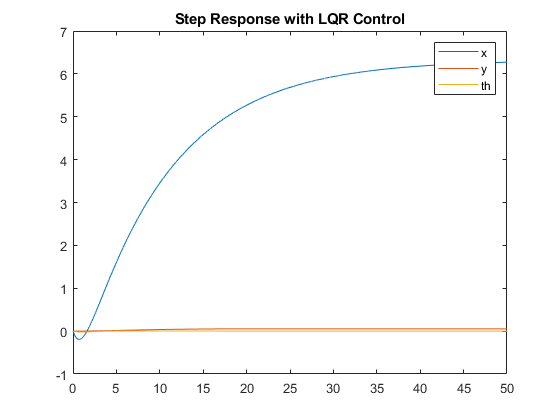

                    
%SIMULATE STATES TO STABILISE
t = 0:0.001:50;
r = 2*ones(length(t), 2);
[y,t,x] = lsim(sys_cl, r, t);

% plot the position states
plot(t, y(:, 4:6));
legend(["x"; "y"; "th"]);
title('Step Response with LQR Control')

% INTERCEPT A MOVING TARGET

% Operating point is zeros and HOVERING, so thrust
% shared among two rotors.
m = m_;
g = g_;
I = I_;

u = [F; al];
dyn = [acceleration_eqns(3); dth];
dyn = subs(dyn, [mass,inertia,g], [m_,I_,g_])

$$dyn = \left(\begin{array}{c} -\frac{240518168576\,F\,\left(\sin\left(\mathrm{al}\right)+\mathrm{al}\,\cos\left(\mathrm{al}\right)\right)}{2531167393109333}\\ \mathrm{dth} \end{array}\right)$$


% OUTPUTS are acceleration: ddx, ddy
Y = subs(acceleration_eqns(1:2), [mass,inertia,g], [m_,I_,g_])

$$Y = \left(\begin{array}{c} -\frac{F\,\left(\sin\left(\mathrm{al}+\mathrm{th}\right)+\mathrm{al}\,\cos\left(\mathrm{al}+\mathrm{th}\right)\right)}{1000}\\ \frac{F\,\cos\left(\mathrm{al}+\mathrm{th}\right)}{1000}-g-\frac{F\,\mathrm{al}\,\sin\left(\mathrm{al}+\mathrm{th}\right)}{1000} \end{array}\right)$$



A = jacobian(dyn, [dth, th]);
A = subs(A,[dth, th, u.'],[0,0,m*g,0])

$$A = \left(\begin{array}{cc} 0 & 0\\ 1 & 0 \end{array}\right)$$


B = jacobian(dyn, [u.']);
B = subs(B,[dth, th, u.'],[0,0,m*g,0]);

% this time weed to linearise the output equation
C = jacobian(Y, [dth, th]);
C = subs(C,[dth, th, u.'],[0,0,m*g,0]);

% and linearise feedforward
D = jacobian(Y, [u.']);
D = subs(D,[dth, th, u.'],[0,0,m*g,0]);

newA = [0, -g, 0, 0;...
        0,  0, 0, 0];
tempA = horzcat(A, zeros(2,2));

% New A Matrix
A_aug = vertcat(tempA, newA);

% New B Matrix
B_aug = vertcat(B, D);

% New C Matrix
newC = [0, 0, 0, 0;...
        0, 0, 0, 0];
tempC = horzcat(C,zeros(2,2));
C_aug = vertcat(tempC, newC);

% New D Matrix - STAYS THE SAME
D_aug = vertcat(D, zeros(2,2));

% get numerical versions (right now they're symbolic)
A = double(A_aug);
B = double(B_aug);
C = double(C_aug);
D = double(D_aug);

% linearized system
states = {'dth' 'th' 'ddxE' 'ddyE'};
inputs = {'u1' 'u2'};
outputs = {'ddx' 'ddy' 'ddxE' 'ddyE'};

sys_ss = ss(A, B, C, D, 'statename', states,...
                        'inputname', inputs,...
                        'outputname', outputs)

sys_ss =
 
  A = 
           dth     th   ddxE   ddyE
   dth       0      0      0      0
   th        1      0      0      0
   ddxE      0  -9.81      0      0
   ddyE      0      0      0      0
 
  B = 
             u1      u2
   dth        0  -1.864
   th         0       0
   ddxE       0  -19.62
   ddyE   0.001       0
 
  C = 
           dth     th   ddxE   ddyE
   ddx       0  -9.81      0      0
   ddy       0      0      0      0
   ddxE      0      0      0      0
   ddyE      0      0      0      0
 
  D = 
             u1      u2
   ddx        0  -19.62
   ddy    0.001       0
   ddxE       0       0
   ddyE       0       0
 
Continuous-time state-space model.



                    
                    
% LQR - regulator/stabilising states
Q = eye(4);
Q(1,1) = 1000;
Q(2,2) = 1000;
Q(3,3) = 1;
Q(4,4) = 1000000000;
R = eye(2);
R(2,2) = 100000000;

% calculate LQR gain
K = lqr(A, B, Q, R)

K = 	1.0e+04 *

    0.0000    0.0000   -0.0000    3.1623
   -0.0000   -0.0000    0.0000    0.0000


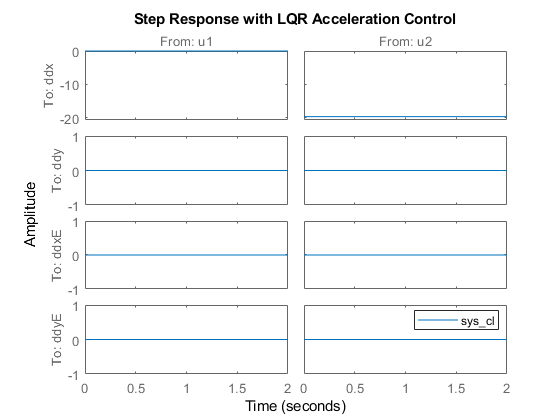


% closed loop
Ac = [(A-B*K)];
Br = [0 0; 0 0; -1 0; 0 -1];
Cc = [C];
Dc = [D];

sys_cl = ss(Ac, Br, Cc, Dc, 'statename', states,...
                            'inputname', inputs,...
                            'outputname', outputs);

t = 0:0.001:2;
step(sys_cl, t)
legend
title('Step Response with LQR Acceleration Control')

% %AUGMENTED LQR STATES
% % New integrator states for error on positions x and y
% newA = [0, 0, 0, 1, 0, 0, 0, 0;...
%         0, 0, 0, 0, 1, 0, 0, 0];
% tempA = horzcat(A, zeros(6,2));
% 
% % New A Matrix (aug = augmented)
% A_aug = vertcat(tempA, newA);
% 
% % New B Matrix
% B_aug = vertcat(B, zeros(2,2));
% 
% % New C matrix
% C_aug = eye(8);
% 
% % weighting system - Weighting integral states more
% % for SS tracking
% Q = eye(8);
% Q(1,1) = 1000;
% Q(2,2) = 1000000;
% Q(3,3) = 10;
% Q(4,4) = 10;
% Q(5,5) = 10000;
% Q(6,6) = 10;
% Q(7,7) = 10;
% Q(8,8) = 10;
% 
% R = eye(2);
% 
% % calculate new LQR gain
% K_aug = lqr(A_aug, B_aug, Q, R)
% 
% %SIMULATING NEW LQR STATES
% 
% Ac = [(A_aug - B_aug*K_aug)];
% Bc = [B_aug];
% Cc = [C_aug];
% Dc = [D];
% 
% states = {'dx' 'dy' 'dth' 'x' 'y' 'th' 'xInt' 'yInt'};
% inputs = {'u1' 'u2'};
% outputs = {'dx' 'dy' 'dth' 'x' 'y' 'th' 'xInt' 'yInt'};
% 
%  sys_cl = ss(Ac, Bc, Cc, Dc, 'statename', states,...
%                              'inputname', inputs,...
%                              'outputname', outputs);
% 
% t = 0:0.001:50;
% r = 2*ones(length(t), 2);
% [y,t,x] = lsim(sys_cl, r, t);
% plot(t, y);
% legend(states)
% title('Step Response with Aug LQR of integrated states');
